clearvars -except object;

% Load structure

atoms = load("atomlistxyz.mat");
elements = atoms.e;
xmax = atoms.mx;
ymax = atoms.my;
zmax = atoms.mz;
xe = xmax*atoms.x;
ye = ymax*atoms.y;
ze = zmax*atoms.z;
msd = atoms.dwf;
clear atoms;

% FFT parameters

sampling = 1024;
vec = [1:sampling]-ceil((sampling+1)*0.5); % include 0 frequency for fftshift
kxv = vec/xmax;
kyv = vec/ymax;
[kx,ky] = meshgrid(kxv,kyv);
ks = kx.^2+ky.^2;
fftnorm = sampling^2/(xmax*ymax);

clearvars kxv kyv vec;

% Probe parameters

cnvangle = 20; % mrad
energy = 200; % keV
beamcurrent = 10*10000/1.60218; % 10 pA to #electrons in 1ms

lambda = 12.39842/(energy*sqrt(1+1021.9979/energy)); % A
k = 1/lambda; % 1/A
gamma = 1/sqrt(1-energy*0.0039139); % relativistic correction

clearvars energy;

% Multislice paramters

dz = 3.867; % A
thetax = 0; % mrad
thetay = 0; % mrad

% Prepare slices

ze = uint8(ceil(ze/dz));
numslices = max(ze);
ellist = unique(elements);

% Prepare potentials

Vklist = zeros(sampling, sampling, numel(ellist));
tempot = load("potentials.mat");

for i=1:numel(ellist)
    el = find(strcmp(tempot.e,ellist(i)));
    Vk = tempot.a1(el)./(ks+tempot.b1(el))+tempot.c1(el)*exp(-tempot.d1(el)*ks);
    Vk = Vk + tempot.a2(el)./(ks+tempot.b2(el))+tempot.c2(el)*exp(-tempot.d2(el)*ks);
    Vk = Vk + tempot.a3(el)./(ks+tempot.b3(el))+tempot.c3(el)*exp(-tempot.d3(el)*ks);
    Vklist(:,:,i) = Vk;
end

clearvars tempot Vk el;

% Create object potential

atomgrid = zeros(sampling, sampling, numslices);
object = zeros(sampling, sampling, numslices);
for i=1:numel(ellist)
    intemp = find(strcmp(elements,ellist(i)));
    xtemp = xe(intemp);
    ytemp = ye(intemp);
    ztemp = ze(intemp);
    dtemp = msd(intemp);
    atomgrid = atomgrid*0;
    for j=1:numel(xtemp)
        atomgrid(:,:,ztemp(j)) = atomgrid(:,:,ztemp(j)) + exp(-2*pi^2*ks*dtemp(i)^2-1i*2*pi*(xtemp(j)*kx+ytemp(j)*ky));
    end
    object = object + ifft2(fftshift(atomgrid.*Vklist(:,:,i)));
end

object = real(object)*fftnorm;

clearvars atomgrid Vklist intemp xtemp ytemp ztemp dtemp ellist elements msd xe ye ze mzero;

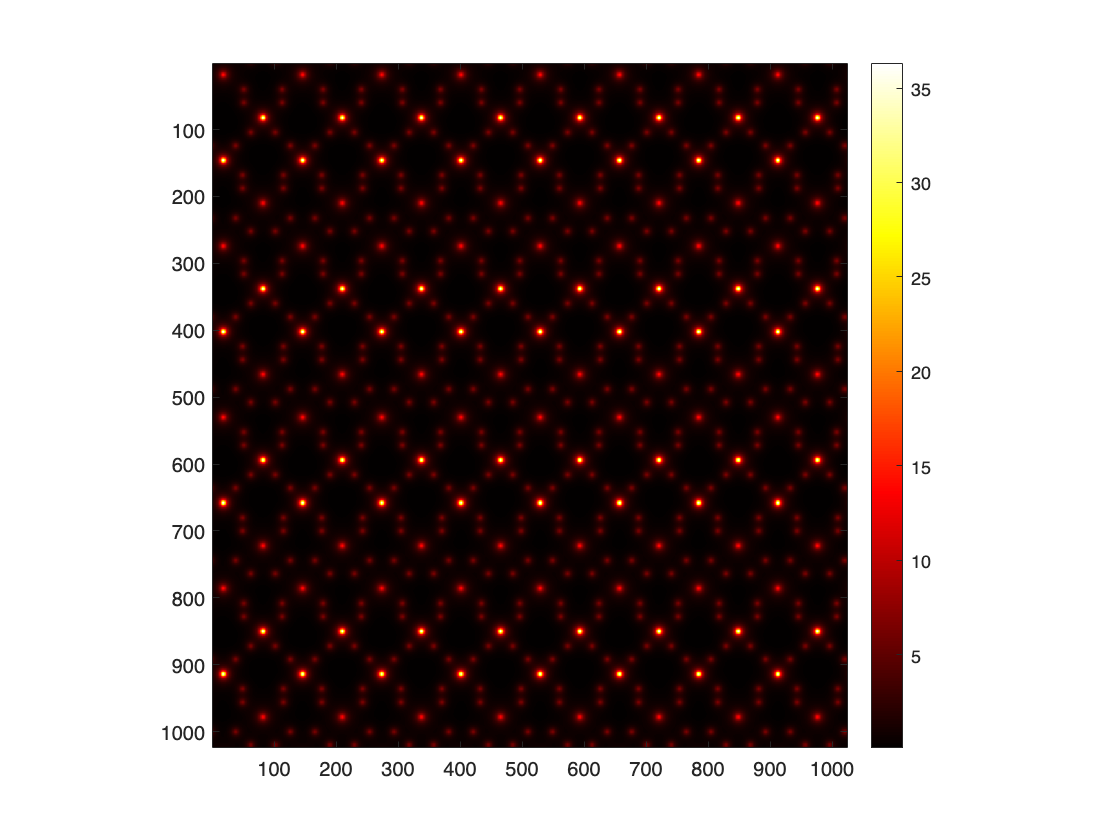

% Visualize object

imagesc(object(:,:,17))
pbaspect([xmax ymax 1]);
colormap("hot");
colorbar();

% Max transmission funtion phase shift

gamma*lambda*max(object(:,:,25),[],"all")

ans = 1.9546

% Create probe and propagator

probex = 15;
probey = 15;

probek = sqrt(ks);
probek(probek>cnvangle*k/1000)=0;
probek(probek>0)=1;
probek = probek*sqrt(beamcurrent/sum(abs(probek).^2,"all"));

translate = exp(-1i*2*pi*(probex*kx+probey*ky));
probek = probek.*translate;
probek = fftshift(probek);

%clearvars translate cnvangle probex probey beamcurrent;

propagator = exp(-1i*pi*ks*lambda*dz+2*pi*1i*(kx*thetax+ky*thetay)*dz/1000);
propagator = fftshift(propagator);

%clearvars thetax thetay;

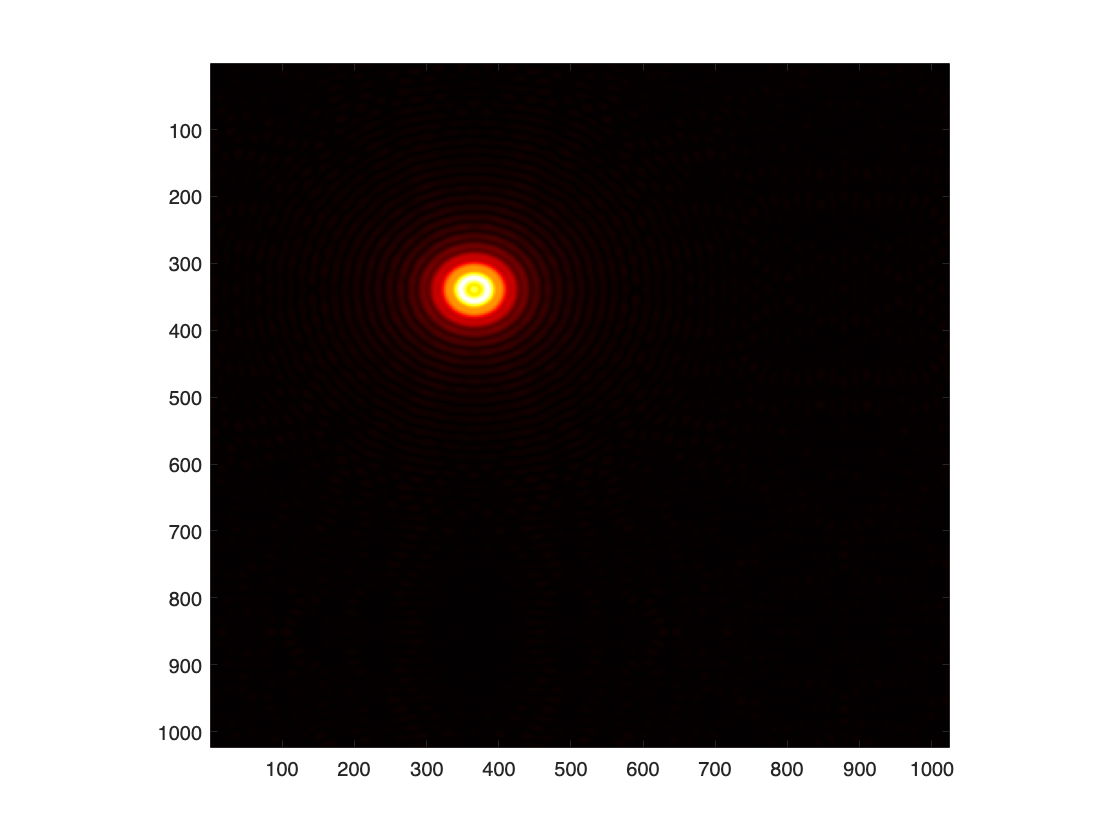

% Aberrations

probek = probek.*fftshift(exp(-1i*pi*ks*lambda*100));

imagesc(abs(ifft2(probek)))
colormap("hot");
pbaspect([ymax xmax 1]);

% Multislice

for i=1:numel(object(1,1,:))
    probek = fft2(ifft2(probek).*exp(1i*gamma*lambda*object(:,:,i))); % transmit
    probek = probek.*propagator; % propagate
end

% Choose detector

ffprobek = abs(fftshift(probek)).^2;
maxkanglex = k*63*xmax/1000; % detector limit (63 mrad here) in 1/A
maxkangley = k*63*ymax/1000;
detlimx = floor(-maxkanglex+sampling/2):floor(maxkanglex+sampling/2);
detlimy = floor(-maxkangley+sampling/2):floor(maxkangley+sampling/2);

clearvars maxkanglex maxkangley;

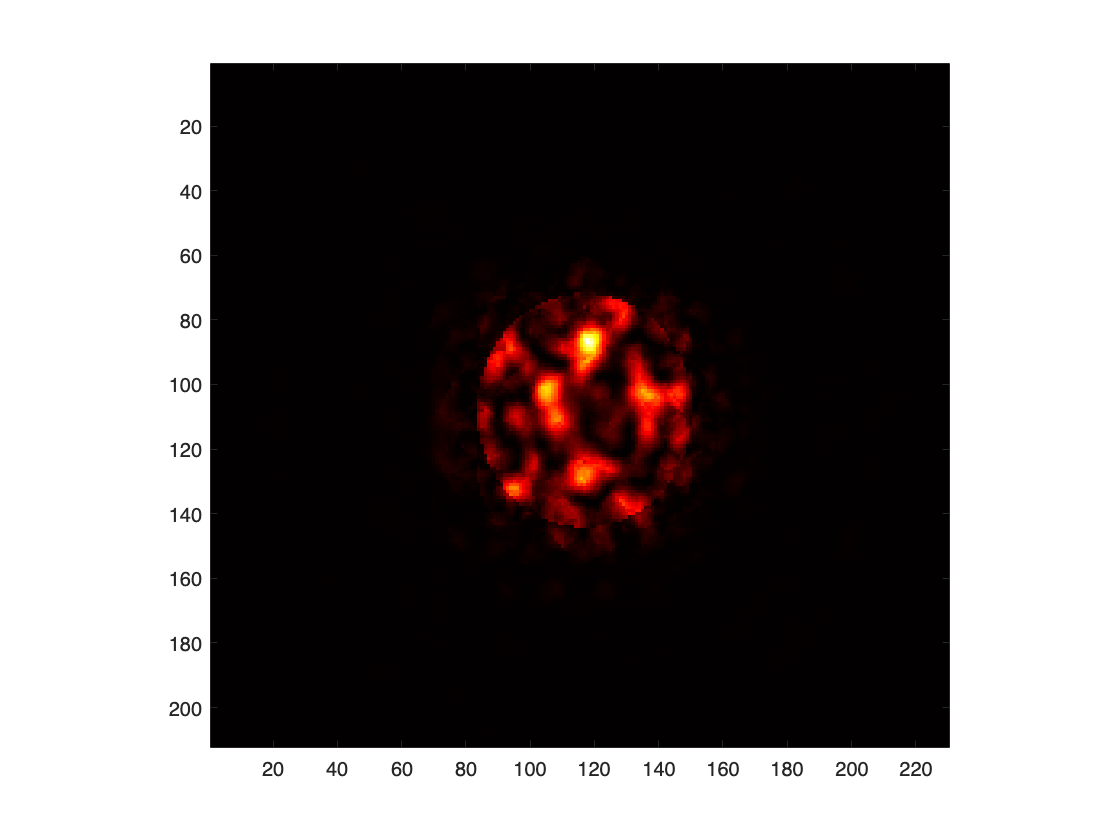

% Simulated CBED pattern

imagesc(ffprobek(detlimx,detlimy))
pbaspect([ymax xmax 1]);
colormap("hot");